close("all"); clear; clc;
setmadsympath;

t = sym('t');
N = Frame;
O = Point;

## Camera pose

Locate and orient camera pose wrt motorcycle.

### Orientation

yaw = DynamicVariable("psi");
camber = DynamicVariable("gamma");
pitch = DynamicVariable("theta");
tilt = sym('mu',{'real','positive'});

Ny = N.orientNew('z',yaw.state);
Nc = Ny.orientNew('x',camber.state);
Np = Nc.orientNew('y',pitch.state);
Nt = Np.orientNew('y',tilt);
Nb = Nt.orientNew('xy',[-pi/2,pi/2]);

### Position

px = DynamicVariable('x');
py = DynamicVariable('y');
pz = DynamicVariable('z');

rb = [
    px.state;
    py.state;
    pz.state
    ];

Ob = O.locateNew(rb);

## Generalized coordinates

q = [
    yaw;
    camber;
    pitch;
    px;
    py;
    pz
    ];

## Quasi-velocities

wx = DynamicVariable('omega_x');
wy = DynamicVariable('omega_y');
wz = DynamicVariable('omega_z');
vx = DynamicVariable('v_x');
vy = DynamicVariable('v_y');
vz = DynamicVariable('v_z');

u = [
    wx;
    wy;
    wz;
    vx;
    vy;
    vz
    ];

## Kinematics

V = Twist(Pose(Nb,Ob)).vector;

eomk = u.state - V;

[Mk,fk] = massMatrixForm(eomk,q.state);
Mk = simplify(expand(Mk));
qd = simplify(expand(syminv(Mk)*fk));

## Geometric parameters

tr = sym('t_r',{'real','positive'});
rr = sym('rho_r',{'real','positive'});
h = sym('h_c',{'real','positive'});
p = sym('p',{'real','positive'});

## Rear contact point

Or = Ob.locateNew(-(h - rr).*Np.z - p.*Np.x);
Oc = Or.locateNew(-rr.*Nc.z - tr.*Ny.z);
rc = simplify(expand(posFrom(Oc)));
pprint(rc);

$$\left[\begin{array}{c} x-c_{\psi }\,c_{\theta }\,p-c_{\psi }\,h_{c}\,s_{\theta }+c_{\psi }\,\rho_{r}\,s_{\theta }-\rho_{r}\,s_{\gamma }\,s_{\psi }-c_{\theta }\,h_{c}\,s_{\gamma }\,s_{\psi }+c_{\theta }\,\rho_{r}\,s_{\gamma }\,s_{\psi }+p\,s_{\gamma }\,s_{\psi }\,s_{\theta }\\ y-c_{\theta }\,p\,s_{\psi }+c_{\psi }\,\rho_{r}\,s_{\gamma }-h_{c}\,s_{\psi }\,s_{\theta }+\rho_{r}\,s_{\psi }\,s_{\theta }+c_{\psi }\,c_{\theta }\,h_{c}\,s_{\gamma }-c_{\psi }\,c_{\theta }\,\rho_{r}\,s_{\gamma }-c_{\psi }\,p\,s_{\gamma }\,s_{\theta }\\ z-t_{r}-c_{\gamma }\,\rho_{r}-c_{\gamma }\,c_{\theta }\,h_{c}+c_{\gamma }\,c_{\theta }\,\rho_{r}+c_{\gamma }\,p\,s_{\theta } \end{array}\right]$$

## Rear contact velocity

drc = simplify(expand(dcm(Ny).'*diff(rc,t)));
drc = simplify(expand(subs(drc,q.rate,qd)));
Arc = jacobian(drc,u.state);
Arc = simplify(expand(Arc));
pprint(Arc);

$$\left[\begin{array}{cccccc} c_{\theta }\,h_{c}-c_{\theta }\,\rho_{r}-p\,s_{\theta } & \frac{\rho_{r}\,s_{\gamma }\,\cos\left(\mu +\theta \right)}{c_{\gamma }} & \frac{\rho_{r}\,s_{\gamma }\,\sin\left(\mu +\theta \right)}{c_{\gamma }} & 0 & -\sin\left(\mu +\theta \right) & \cos\left(\mu +\theta \right)\\ s_{\gamma }\,\left(c_{\theta }\,p+h_{c}\,s_{\theta }-\rho_{r}\,s_{\theta }\right) & c_{\gamma }\,\left(c_{\mu }\,p-h_{c}\,s_{\mu }+\rho_{r}\,s_{\mu }-\rho_{r}\,\sin\left(\mu +\theta \right)\right) & c_{\gamma }\,\left(c_{\mu }\,h_{c}-c_{\mu }\,\rho_{r}+p\,s_{\mu }+\rho_{r}\,\cos\left(\mu +\theta \right)\right) & -c_{\gamma } & s_{\gamma }\,\cos\left(\mu +\theta \right) & s_{\gamma }\,\sin\left(\mu +\theta \right)\\ -c_{\gamma }\,\left(c_{\theta }\,p+h_{c}\,s_{\theta }-\rho_{r}\,s_{\theta }\right) & s_{\gamma }\,\left(c_{\mu }\,p-h_{c}\,s_{\mu }+\rho_{r}\,s_{\mu }-\rho_{r}\,\sin\left(\mu +\theta \right)\right) & s_{\gamma }\,\left(c_{\mu }\,h_{c}-c_{\mu }\,\rho_{r}+p\,s_{\mu }+\rho_{r}\,\cos\left(\mu +\theta \right)\right) & -s_{\gamma } & -c_{\gamma }\,\cos\left(\mu +\theta \right) & -c_{\gamma }\,\sin\left(\mu +\theta \right) \end{array}\right]$$

## Camera vertical speed

eqn = Arc(3,:)*u.state;
eqn = rhs(isolate(eqn == 0,vz.state));
eqn = simplify(expand(eqn));

Avz = jacobian(eqn,u(1:5).state);
Avz = simplify(expand(Avz));
pprint(Avz);

$$\left[\begin{array}{ccccc} -\frac{c_{\theta }\,p+h_{c}\,s_{\theta }-\rho_{r}\,s_{\theta }}{\sin\left(\mu +\theta \right)} & \frac{s_{\gamma }\,\left(c_{\mu }\,p-h_{c}\,s_{\mu }+\rho_{r}\,s_{\mu }-\rho_{r}\,\sin\left(\mu +\theta \right)\right)}{c_{\gamma }\,\sin\left(\mu +\theta \right)} & \frac{s_{\gamma }\,\left(c_{\mu }\,h_{c}-c_{\mu }\,\rho_{r}+p\,s_{\mu }+\rho_{r}\,\cos\left(\mu +\theta \right)\right)}{c_{\gamma }\,\sin\left(\mu +\theta \right)} & -\frac{s_{\gamma }}{c_{\gamma }\,\sin\left(\mu +\theta \right)} & -\frac{\cos\left(\mu +\theta \right)}{\sin\left(\mu +\theta \right)} \end{array}\right]$$

## MATLAB functions

params = [
    tilt;
    h;
    p;
    rr;
    tr
    ].';

vars = {
    prettify(q(1:3).state.');
    params
    }.';

nm = "rearContactVelocityJacobian";
matlabFunction(prettify(Arc), ...
    'File',nm, ...
    'Vars',vars);

nm = "verticalSpeedJacobian";
matlabFunction(prettify(Avz), ...
    'File',nm, ...
    'Vars',vars);

## Validation

speed = num2str(130);
scen = "DLC";
res_path = "G:\My Drive\BikeSimResults\BigSports\";
scen_path = scen + "\Vx" + speed + "Kph\";
file_name = "bikesim_results_" + speed + "kph.csv";
ref = readtable(res_path + scen_path + file_name);
n = height(ref);

### Orientation

yaw = deg2rad(ref.Yaw);
pitch = deg2rad(ref.Pitch);
roll = deg2rad(ref.Roll_E);

R = angle2dcm(yaw,pitch,roll);
[yaw,camber,pitch] = dcm2angle(R,'ZXY');

q = [yaw,camber,pitch];

### Twist

tform = rigidtform3d(rotx(90).'*roty(90),[0,0,0]);

wx = ref.AVx_S1;
wy = ref.AVy_S1;
wz = ref.AVz_S1;
w = deg2rad([wx,wy,wz]);
w = transformPointsInverse(tform,w);

vx = ref.Vx_S1;
vy = ref.Vy_S1;
vz = ref.Vz_S1;
v = [vx,vy,vz]./3.6;

v = transformPointsInverse(tform,v);

u = [w,v];

### Geometric parameters

tilt = deg2rad(20);
p = 1.37 - 0.0896;
h = 0.9098;
Rr = 0.297;
tr = 70E-03;
rr = Rr - tr;

pars = [
    tilt;
    h;
    p;
    rr;
    tr
    ].';

### Rear contact velocity

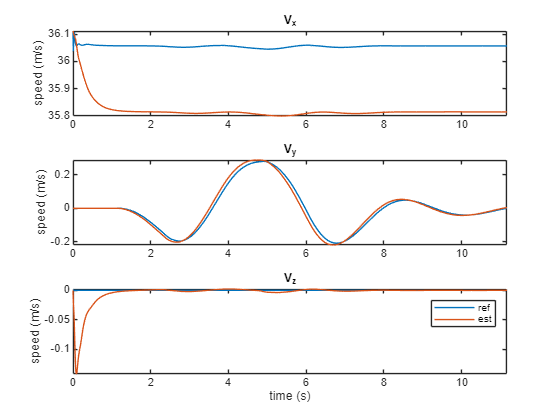

vCr = [ref.VxCGC_2,ref.VyCGC_2,zeros(n,1)]./3.6;

f = @rearContactVelocityJacobian;
Arc = zeros(3,6,n);
for k = 1:n
    Arc(:,:,k) = f(q(k,:),pars);
end

vCr_est = pagemtimes(Arc,reshape(u.',6,1,[]));
vCr_est = reshape(vCr_est,3,[]).';

fig = figure;
tl = tiledlayout(3,1,'Parent',fig);
nm = 'xyz';
for k = 1:3
    axe = nexttile(tl,k);
    hold(axe,'on');
    plot(axe,ref.Time,vCr(:,k));
    plot(axe,ref.Time,vCr_est(:,k));
    hold(axe,'off');
    box(axe,'on');
    axis(axe,'tight');
    title("V_" + nm(k));
    ylabel(axe,'speed (m/s)');
end
xlabel(axe,'time (s)');
legend(axe,'ref','est');

### Camera vertical speed

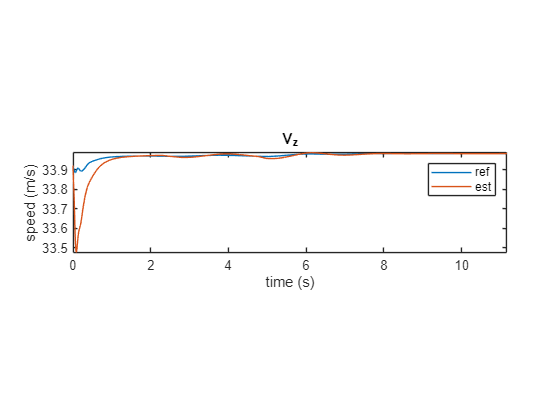

f = @verticalSpeedJacobian;
Avz = zeros(1,5,n);
for k = 1:n
    Avz(:,:,k) = f(q(k,:),pars);
end

vz_est = pagemtimes(Avz,reshape(u(:,1:5).',5,1,[]));
vz_est = reshape(vz_est,1,[]).';

fig = figure;
axe = axes(fig);
hold(axe,'on');
plot(axe,ref.Time,u(:,6));
plot(axe,ref.Time,vz_est);
hold(axe,'off');
box(axe,'on');
axis(axe,'tight');
title(axe,'V_z');
xlabel(axe,'time (s)');
ylabel(axe,'speed (m/s)');
legend(axe,'ref','est');
daspect(axe,[5,1,1]);